clear all
close all
clc

**2.1 Probabilidade**

3. Considere um array de tamanho T que serve de base a implementacao de uma memoria associativa (por exemplo em Java). Assuma que a funcao de hash devolve um valor entre 0 e T −1 com todos os valores igualmente prov´ aveis. 

(a) Determine por simulacao a probabilidade de haver pelo menos uma colisao (pelo menos 2 keys mapeadas pela funcao de hash para a mesma posicao do array) se forem introduzidas 10 keys num array de tamanho T = 1000. 

N = 1e5;
keys = 10;
T = 1000;
colisoes = 0;

for sim = 1:N
    valores = randi(T, 1, keys);
    if length(unique(valores)) < keys
        colisoes = colisoes + 1;
    end
end
probabilidade = colisoes/N

probabilidade = 0.0442

(b) Faca um grafico da probabilidade da alinea (a) (estimada por simulacao) em funcao do numero de keys para todos os valores relevantes num array de tamanho T = 1000. 

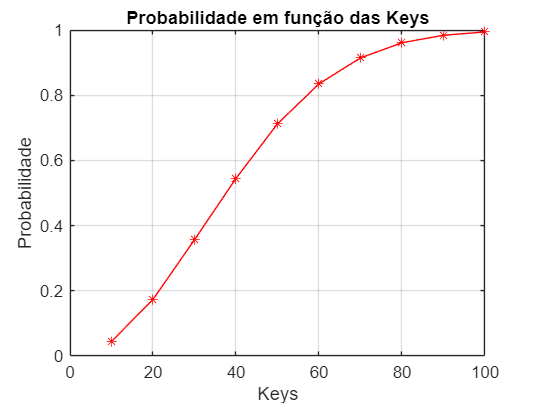

tic
N = 1e5;
keys = 10:10:100;
T = 1000;
res = zeros(1,length(keys));

for i = 1:length(keys)
    key = keys(i);
    colisoes = 0;
    for sim = 1:N
        valores = randi(T, 1, key);
        if length(unique(valores)) < key
            colisoes = colisoes + 1;
        end
    end
    res(i) = colisoes/N;
end
figure(1);
plot(keys, res, 'r*-'), xlabel('Keys'), ylabel('Probabilidade'), title('Probabilidade em função das Keys'), grid on;

toc

Elapsed time is 7.223172 seconds.


(c) Para um numero de keys igual a 50, represente graficamente a variacao da probabilidade (esti mada por simulacao) de nao haver nenhuma colisao em funcao do tamanho T do array (assuma os tamanhos T de 100 ate 1000 com incrementos de 100).